# Stock Data - Value at Risk Simulations

## 1.

Run the script `stockDataDistributionFitting.mlx`from the exercise *Stock Data – Distribution Fitting*. This script creates four distributions that are stored in the cell array `retFits`.

MHRret =          0
   -0.0328
    0.0328
   -0.0245
    0.0082
   -0.0165
   -0.0426
         0
   -0.1298
    0.0099


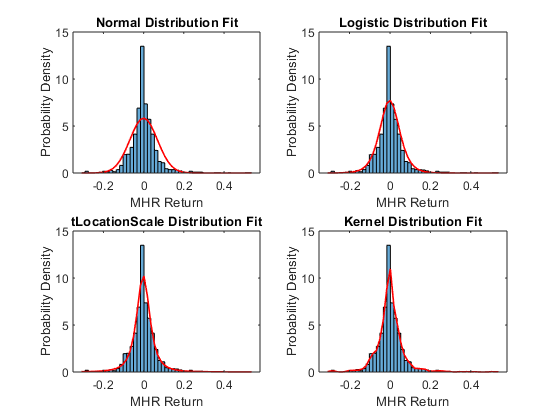

stockDataDistributionFitting

## 2. 

Create a 10000-by-4 matrix of simulated returns using the `random `function. Each column of the matrix should contain 10000 random numbers from a different distribution in `retFits`.

nSims = 10000;
simRets = zeros(nSims,4);
for i = 1:length(retFits)
    simRets(:,i) = random(retFits{i},nSims,1);
end

## 3.

Compute the 95% Value-at-Risk (VaR) for each column of the simulated returns. To calculate the VaR, find the value of the simulated return at a percentile threshold of 5%.

VaR = prctile(simRets, 5)

VaR =    -0.1110   -0.0976   -0.1010   -0.0993


## 4.

Visualize the VaR values for each distribution as bar series using the following steps:

- Return two outputs (the bin counts and edges) from the `histcounts `function (use 50 bins).

- Compute the center of each bin from the bin edges.

- Identify the bin centers that are less than the VaR.

- Create bar series of the bin centers below the VaRin red, and above the VaR in green.

- Draw each distribution in a separate subplot.

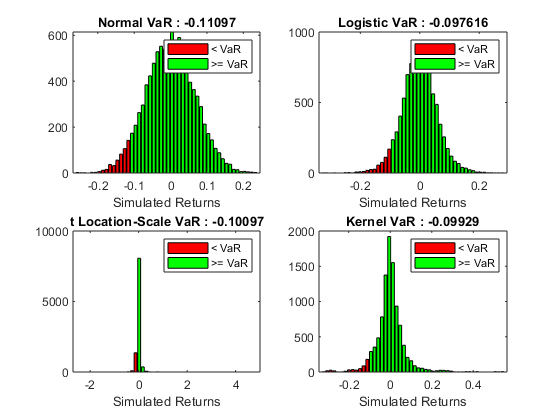

for k = 1:length(retFits)
    [binCounts, binEdges] = histcounts(simRets(:,k),50);
    binCenters = (binEdges(1:end-1) + binEdges(2:end))/2;
    % Find bins lower than VaR threshold
    lowerVaR = binCenters < VaR(k);    
    subplot(2,2,k)
    bar(binCenters(lowerVaR), binCounts(lowerVaR), 'r')
    hold on
    bar(binCenters(~lowerVaR), binCounts(~lowerVaR), 'g')
    xlabel('Simulated Returns')
    title([retFits{k}.DistributionName, ' VaR : ', num2str(VaR(k))])
    legend({'< VaR','>= VaR'})
end